# BPSK Modulator Simulation

## Theoretical background

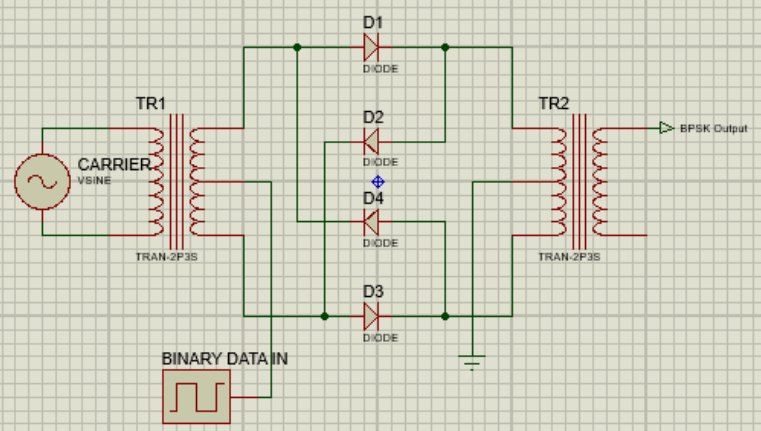

- Above is a BPSK modulator which uses a balanced modulator. 

- The carrier wave is a high frequency sinusoidal wave and the binary data input waveform is a square wave of amplitudes +1 V and -1 V corresponding to binary values 1 and 0 respectively. 

- The diodes control the "orientation" of the sine wave that is passed through the transformer TR2. When the binary data input is +1 V, the BPSK output is equal to the carrier wave, or has no phase difference. When the binary data input is - 1 V, the BPSK output and the carrier wave will have a 180-degree phase difference, hence the modulation scheme "BPSK".

- The simulation will assume the transformers TR1 and TR2 specifications to be 1:1 and that there is no voltage drop across the diodes. Hence only the phase of the waveforms shall change.

- Below are the expected waveforms (from [What is Phase Shift Keying (PSK)? BPSK modulation, BPSK demodulation, advantages, disadvantages and applications of PSK - Electronics Coach](https://electronicscoach.com/phase-shift-keying.html)):

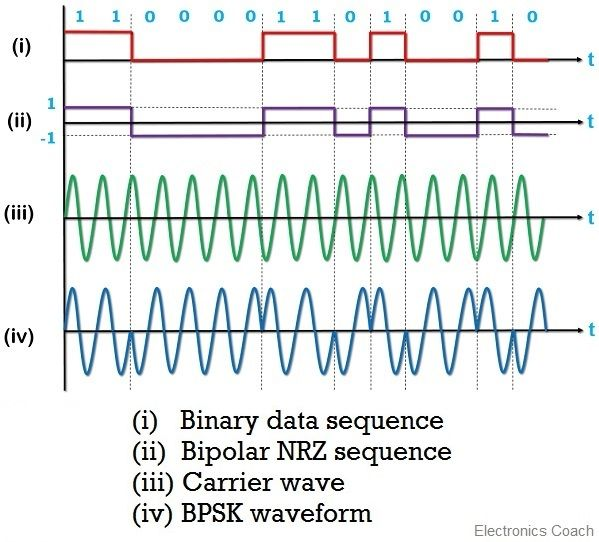

## BPSK modulator (No graphing of the waveforms)

- Scheme for generating the complex envelope is updated to match that of the built in function.

- Simulation without graphing the waveforms can accommodate more input bits since plotting requires 10k times more samples.

### Model the binary data

clear
nbits = 1e6;
bits = randi([0 1], 1, nbits)

bits =      1     0     1     0     0     1     1     0     1     0     1     1     0     0     0     1     1     0     0     1     0     1     1     1     1     0     0     1     1     0     0     1     1     0     1     1     0     1     1     0     0     0     0     0     0     1     0     1     1     1


### Generate the complex envelope

cmplx_env = zeros(size(bits));
for i = 1 : length(bits)
    switch(bits(i))
        case 1
            cmplx_env(i) = -1;
        case 0
            cmplx_env(i) = 1;
        otherwise
            error("Error in bit generation")
    end
end
cmplx_env = complex(cmplx_env)

cmplx_env =   -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i


### Add white Gaussian noise to the complex envelope

SNR = 30;   
noise_cmplx_env = awgn(cmplx_env, SNR)

noise_cmplx_env =   -1.0324 + 0.0449i   1.0282 + 0.0039i  -0.9816 - 0.0170i   0.9740 - 0.0047i   1.0172 + 0.0061i  -1.0046 - 0.0024i  -0.9817 + 0.0018i   1.0203 - 0.0230i  -0.9430 - 0.0058i   1.0110 - 0.0461i  -0.9860 - 0.0065i  -0.9987 - 0.0682i   0.9899 - 0.0150i   1.0195 - 0.0302i   1.0071 + 0.0034i  -0.9592 + 0.0140i  -0.9968 - 0.0187i   1.0046 + 0.0093i   0.9836 - 0.0034i  -1.0069 + 0.0015i   1.0460 - 0.0059i  -1.0172 + 0.0028i  -1.0041 + 0.0038i  -1.0235 + 0.0204i  -1.0121 + 0.0207i   1.0155 - 0.0105i   0.9999 + 0.0011i  -1.0062 + 0.0085i  -0.9633 + 0.0383i   0.9885 + 0.0086i   1.0239 - 0.0366i  -1.0094 - 0.0529i  -1.0180 - 0.0228i   0.9698 + 0.0212i  -0.9512 - 0.0204i  -1.0203 + 0.0109i   0.9603 + 0.0120i  -1.0049 - 0.0044i  -1.0387 - 0.0187i   0.9869 - 0.0529i   1.0315 + 0.0034i   1.0253 + 0.0000i   0.9907 + 0.0140i   0.9984 - 0.0329i   1.0430 - 0.0370i  -1.0048 + 0.0093i   1.0074 - 0.0077i  -0.9818 - 0.0034i  -0.9622 - 0.0060i  -0.9639 - 0.0644i


### Plot the BPSK constellation diagram

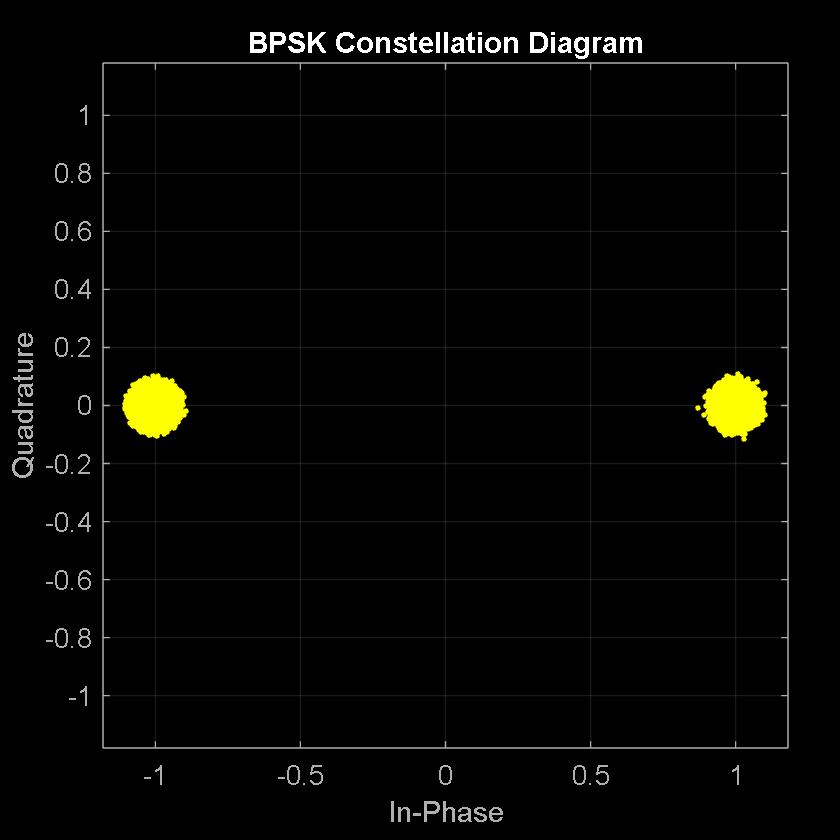

clf
figure
scatterplot(noise_cmplx_env)
title("BPSK Constellation Diagram")
grid on

### Recover the bits from the noisy BPSK-modulated signal

recovered_bits = zeros(size(bits));
for i = 1 : length(noise_cmplx_env)
    if real(noise_cmplx_env(i)) < 0
        recovered_bits(i) = 1;
    elseif real(noise_cmplx_env(i)) >= 0 
        % do nothing since array is already zeros
    else
        error("Error in complex envelope generation")
    end
end
recovered_bits

recovered_bits =      1     0     1     0     0     1     1     0     1     0     1     1     0     0     0     1     1     0     0     1     0     1     1     1     1     0     0     1     1     0     0     1     1     0     1     1     0     1     1     0     0     0     0     0     0     1     0     1     1     1


### Compute for the bit error rate

[number, ratio] = biterr(bits, recovered_bits);
fprintf("For SNR of " + num2str(SNR) + ", the BPSK modulation system produced " + num2str(number) + ...
    " number of bits in error. Resulting BER is " + num2str(ratio*100) + " percent.")

For SNR of 30, the BPSK modulation system produced 0 number of bits in error. Resulting BER is 0 percent.

## Replication of BPSK using built-in MATLAB functions

### Generate the complex envelope using the pskmod() function

complex_envelope = pskmod(bits, 2)

complex_envelope =   -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i


### Add white Gaussian noise to the complex envelope

noise_complex_envelope = awgn(complex_envelope, SNR)

noise_complex_envelope =   -1.0235 + 0.0394i   1.0108 - 0.0078i  -0.9994 - 0.0215i   1.0182 + 0.0310i   1.0323 + 0.0083i  -1.0059 - 0.0158i  -0.9807 - 0.0162i   1.0420 - 0.0043i  -0.9426 - 0.0103i   1.0182 - 0.0147i  -1.0186 - 0.0149i  -1.0226 - 0.0077i   1.0284 - 0.0099i   1.0013 + 0.0067i   1.0214 - 0.0033i  -0.9959 - 0.0078i  -1.0035 - 0.0241i   0.9924 - 0.0224i   0.9895 + 0.0172i  -0.9847 + 0.0149i   0.9895 - 0.0352i  -0.9666 + 0.0396i  -1.0440 - 0.0145i  -0.9819 - 0.0132i  -0.9974 + 0.0124i   0.9823 - 0.0193i   1.0353 - 0.0019i  -0.9637 - 0.0076i  -1.0175 - 0.0157i   0.9885 + 0.0159i   0.9937 - 0.0053i  -0.9748 - 0.0092i  -1.0130 - 0.0526i   1.0022 + 0.0056i  -1.0226 + 0.0052i  -1.0347 + 0.0301i   1.0071 - 0.0088i  -0.9648 - 0.0160i  -1.0086 + 0.0009i   1.0068 - 0.0100i   1.0004 - 0.0155i   0.9676 - 0.0068i   1.0034 + 0.0233i   1.0213 - 0.0113i   0.9880 - 0.0070i  -1.0032 - 0.0333i   0.9896 - 0.0292i  -0.9674 - 0.0466i  -1.0083 - 0.0239i  -1.0138 + 0.0148i


### Plot the BPSK constellation diagram

clf
figure
scatterplot(noise_cmplx_env)
title("BPSK Constellation Diagram")
grid on

### Recover the bits from the noisy BPSK-modulated signal

recovered_bits = pskdemod(noise_cmplx_env, 2)

recovered_bits =      1     0     1     0     0     1     1     0     1     0     1     1     0     0     0     1     1     0     0     1     0     1     1     1     1     0     0     1     1     0     0     1     1     0     1     1     0     1     1     0     0     0     0     0     0     1     0     1     1     1


### Compute for the bit error rate

[number, ratio] = biterr(bits, recovered_bits);
fprintf("For SNR of " + num2str(SNR) + ", the BPSK modulation system produced " + num2str(number) + ...
    " number of bits in error. Resulting BER is " + num2str(ratio*100) + " percent.")

For SNR of 30, the BPSK modulation system produced 0 number of bits in error. Resulting BER is 0 percent.

clear

## Simulation of BPSK modulator

### Model the carrier

fc = 1e6;
Ac = 1;

### Model the binary data

% nbits = 8;
% bits = randi([0 1], 1, nbits)
bits = [1 0 1 0 1 0 0 1]

bits =      1     0     1     0     1     0     0     1


### Generate the binary waveforms

bin = zeros(size(bits));
binwave = [];
NRZ = [];
for i = 1 : length(bin)
    if bits(i) == 1
        bin(i) = 1;
        NRZ = [NRZ ones(1, fc)];
        binwave = [binwave ones(1, fc)];
    elseif bits(i) == 0
        bin(i) = -1;
        NRZ = [NRZ -ones(1, fc)];
        binwave = [binwave zeros(1, fc)];
    end
end

### Generate the carrier waveform

T = linspace(0, length(bin)/fc, length(bin)*fc);
carrier = Ac.*sin(2*pi*fc*T);

### Generate the BPSK-modulated waveform

BPSK = [];
for i = 1 : length(bin)
    if NRZ((i-1)*fc + 1) >= 0
        BPSK = [BPSK carrier(1 : fc)];
    elseif NRZ((i-1)*fc + 1) < 0
        BPSK = [BPSK -carrier(1 : fc)];
    end
end

### Display all generated waveforms

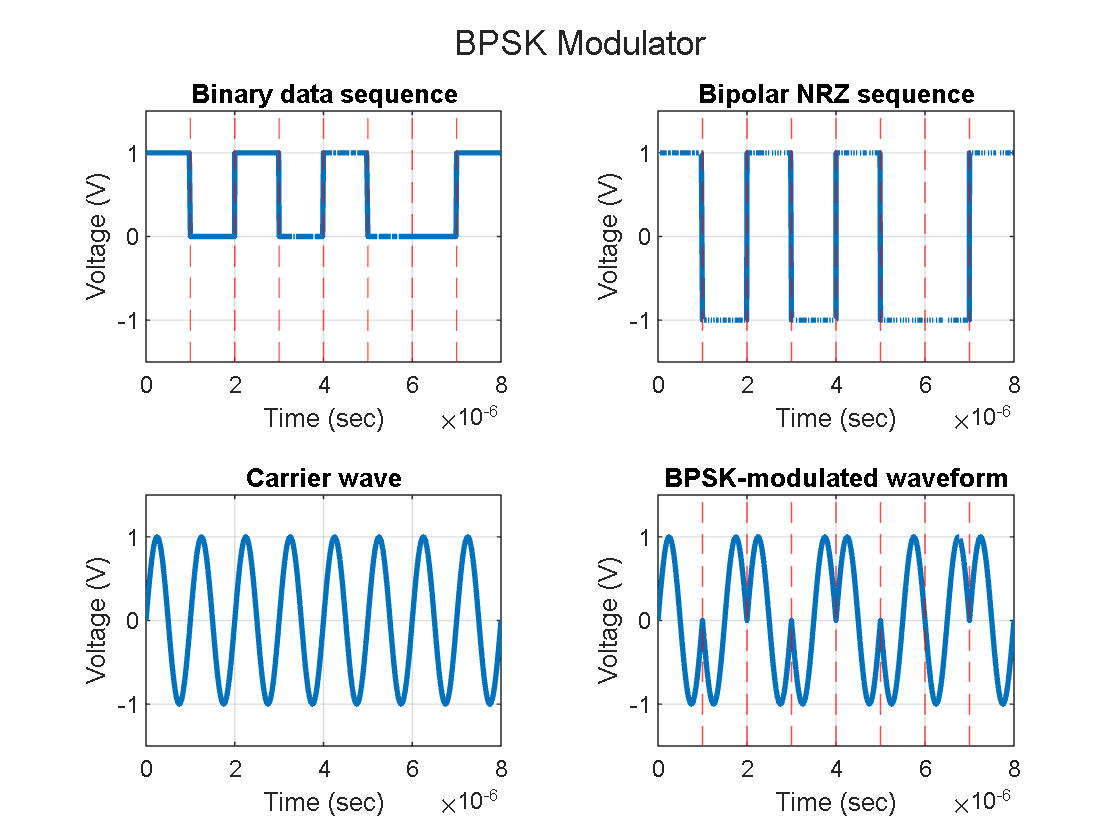

clf
figure
tiledlayout(2, 2)

nexttile % Binary data sequence
plot(T, binwave, LineWidth=2)
title("Binary data sequence")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(T)])
ylim((max(abs(binwave))*(3/2)).*[-1 1])
for i = 1 : length(bin)-1, xline(i/fc, LineStyle='--', Color='red'); end
grid on

nexttile % Bipolar NRZ sequence
plot(T, NRZ, LineWidth=2)
title("Bipolar NRZ sequence")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(T)])
ylim([-2 2])
ylim((max(abs(NRZ))*(3/2)).*[-1 1])
for i = 1 : length(bin)-1, xline(i/fc, LineStyle='--', Color='red'); end
grid on

nexttile % Carrier wave
plot(T, carrier, LineWidth=2)
title("Carrier wave")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(T)])
ylim((Ac*(3/2)).*[-1 1])
grid on

nexttile % BPSK-modulated waveform
plot(T, BPSK, LineWidth=2)
title("BPSK-modulated waveform")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(T)])
ylim((Ac*(3/2)).*[-1 1])
for i = 1 : length(bin)-1, xline(i/fc, LineStyle='--', Color='red'); end
grid on

sgtitle("BPSK Modulator")